# Computer Assignment 5 Solutions

## Step 1 Load the Test Images


clear;
close all;
clc;


Choose a Colormap to use see here for details: https://www.mathworks.com/help/matlab/ref/colormap.html#budgl17-1

cm_defined= "hot";

Choose to use the colormap loaded with images or the one chosen:

UseDefinedColormap=false;

% load images
[im_car, cm_car]=imread("im_car.png");
[im_coins, cm_coins]=imread("im_coins.png");
[im_eagles, cm_eagles]=imread("im_eagles.png");



## Step 2: Lowpass filtering the images

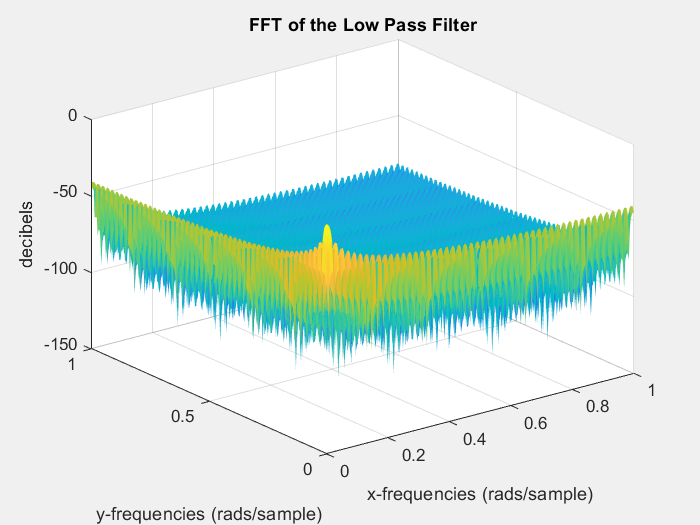

hsize=100;
% construct filter and view it
h=fspecial('average',hsize);
figure;
myFFT2(h)
title('FFT of the Low Pass Filter')

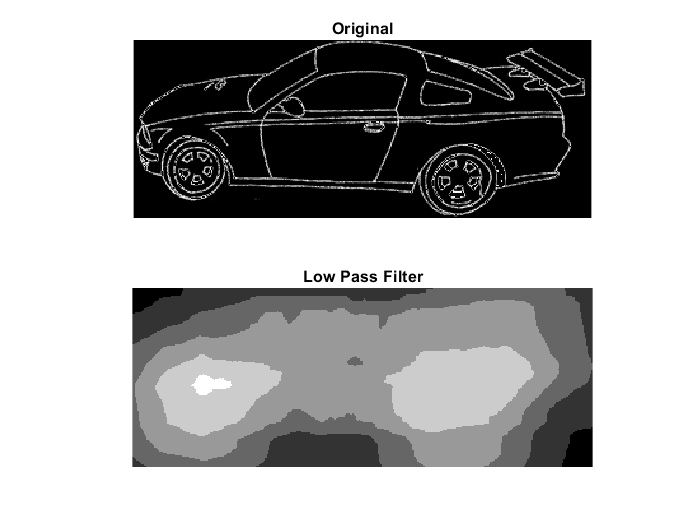

% Filter 3 images
car_filtered=imfilter(im_car,h);
coins_filtered=imfilter(im_coins,h);
eagles_filtered=imfilter(im_eagles,h);

% Display 3 images side by side with original
figure;
subplot(2,1,1)
imshow(im_car, cm_car)
title('Original')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(car_filtered,cm_car)
title("Low Pass Filter")

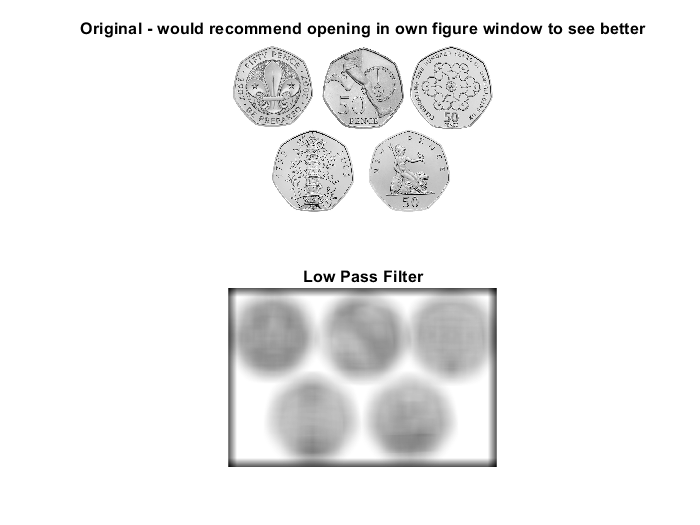

if UseDefinedColormap
    colormap(cm_defined);
end
figure;
subplot(2,1,1)
imshow(im_coins, cm_coins)
title('Original - would recommend opening in own figure window to see better')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(coins_filtered,cm_coins)
title("Low Pass Filter")

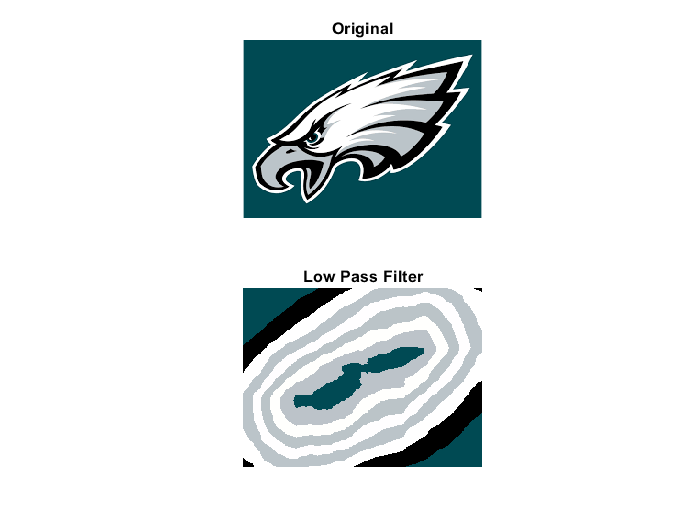

if UseDefinedColormap
    colormap(cm_defined);
end

figure;
subplot(2,1,1)
imshow(im_eagles,cm_eagles)
title('Original')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(eagles_filtered,cm_eagles)
title("Low Pass Filter")

if UseDefinedColormap
    colormap(cm_defined);
end


## Step 3: High Pass Filter the Images

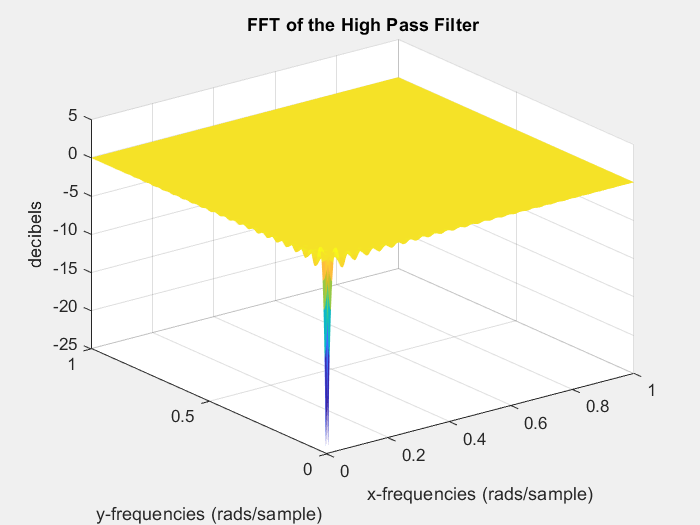

% first construct the high pass filter using the description from the
% assignment

h_high=zeros(size(h));
mid_h_high=floor(hsize/2);
h_high(mid_h_high,mid_h_high)=1;
h_high=h_high-h;
figure;
myFFT2(h_high);
title('FFT of the High Pass Filter')

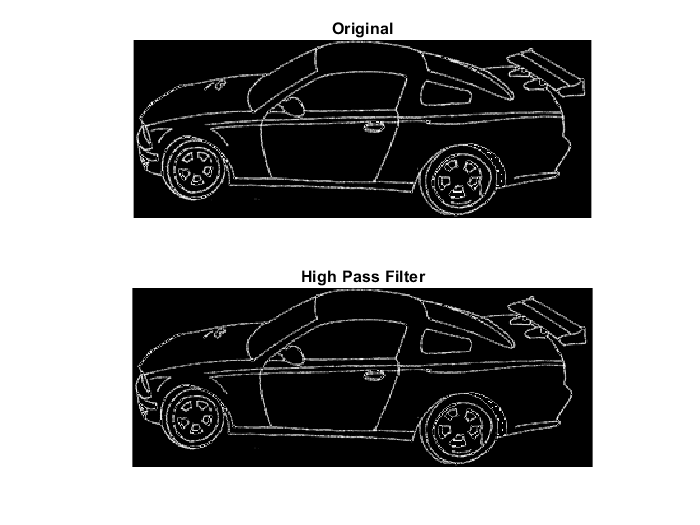

% Filter 3 images
car_filtered=imfilter(im_car,h_high);
coins_filtered=imfilter(im_coins,h_high);
eagles_filtered=imfilter(im_eagles,h_high);

% Display 3 images side by side with original
figure;
subplot(2,1,1)
imshow(im_car, cm_car)
title('Original')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(car_filtered,cm_car)
title("High Pass Filter")

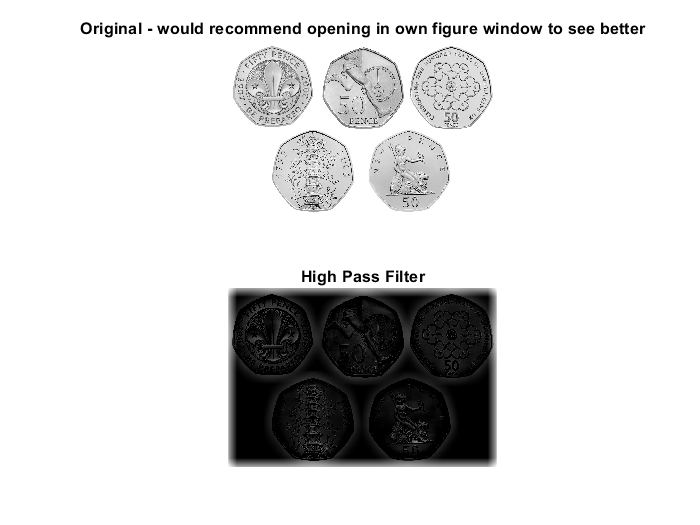

if UseDefinedColormap
    colormap(cm_defined);
end
figure;
subplot(2,1,1)
imshow(im_coins, cm_coins)
title('Original - would recommend opening in own figure window to see better')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(coins_filtered,cm_coins)
title("High Pass Filter")

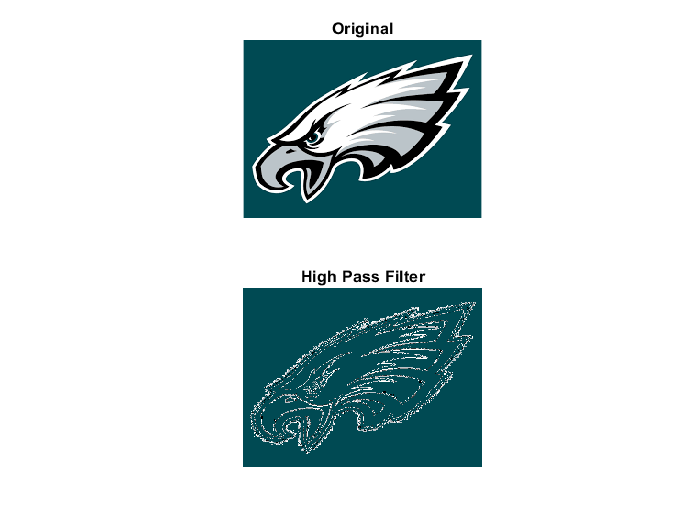

if UseDefinedColormap
    colormap(cm_defined);
end

figure;
subplot(2,1,1)
imshow(im_eagles,cm_eagles)
title('Original')
if UseDefinedColormap
    colormap(cm_defined);
end
subplot(2,1,2)
imshow(eagles_filtered,cm_eagles)
title("High Pass Filter")

if UseDefinedColormap
    colormap(cm_defined);
end


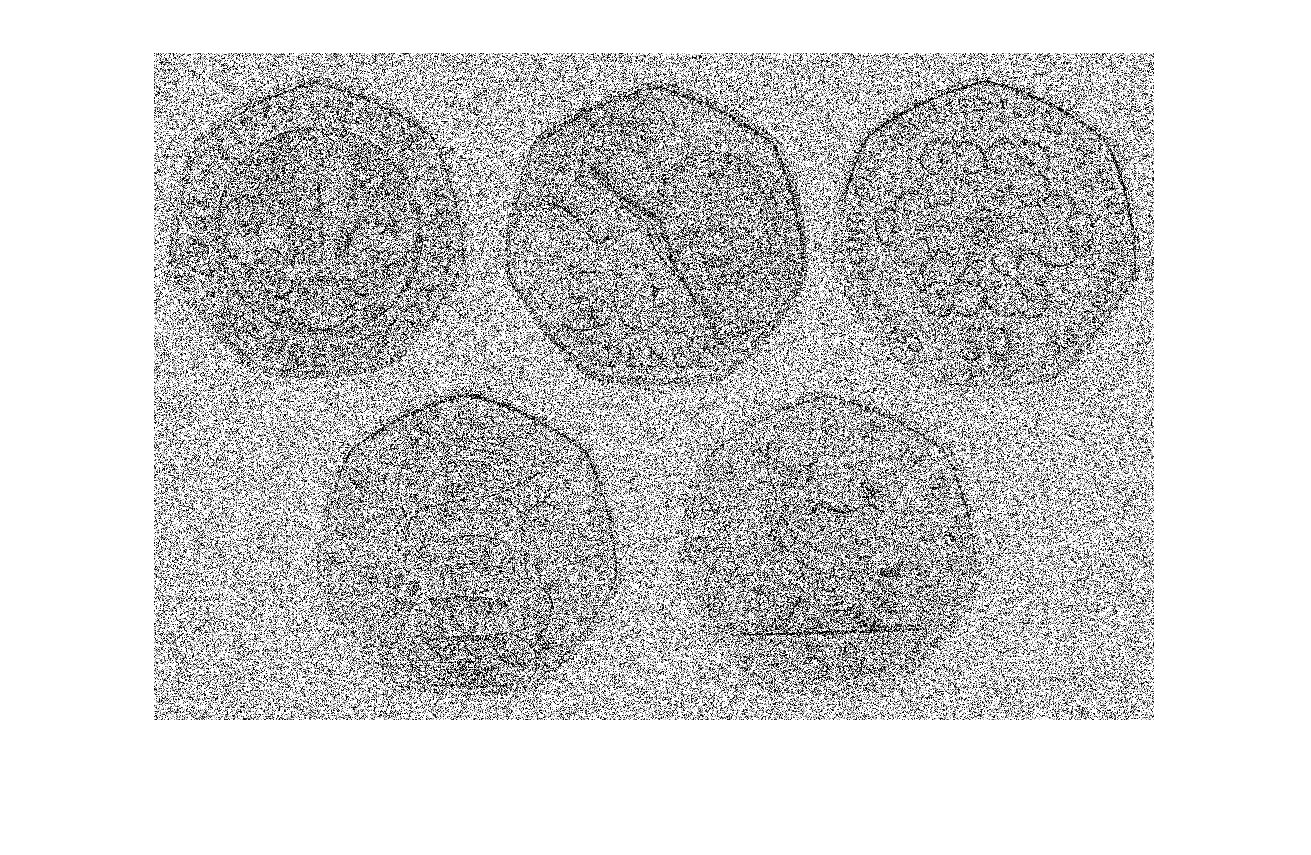

close all
clear all
clc
[im_coins, cm_coins]=imread("im_coins_noisy.png");
hsize=7;
hsize2=97;
h=fspecial('average',hsize);
coins_filtered=imfilter(im_coins,h);
imshow(im_coins, cm_coins);

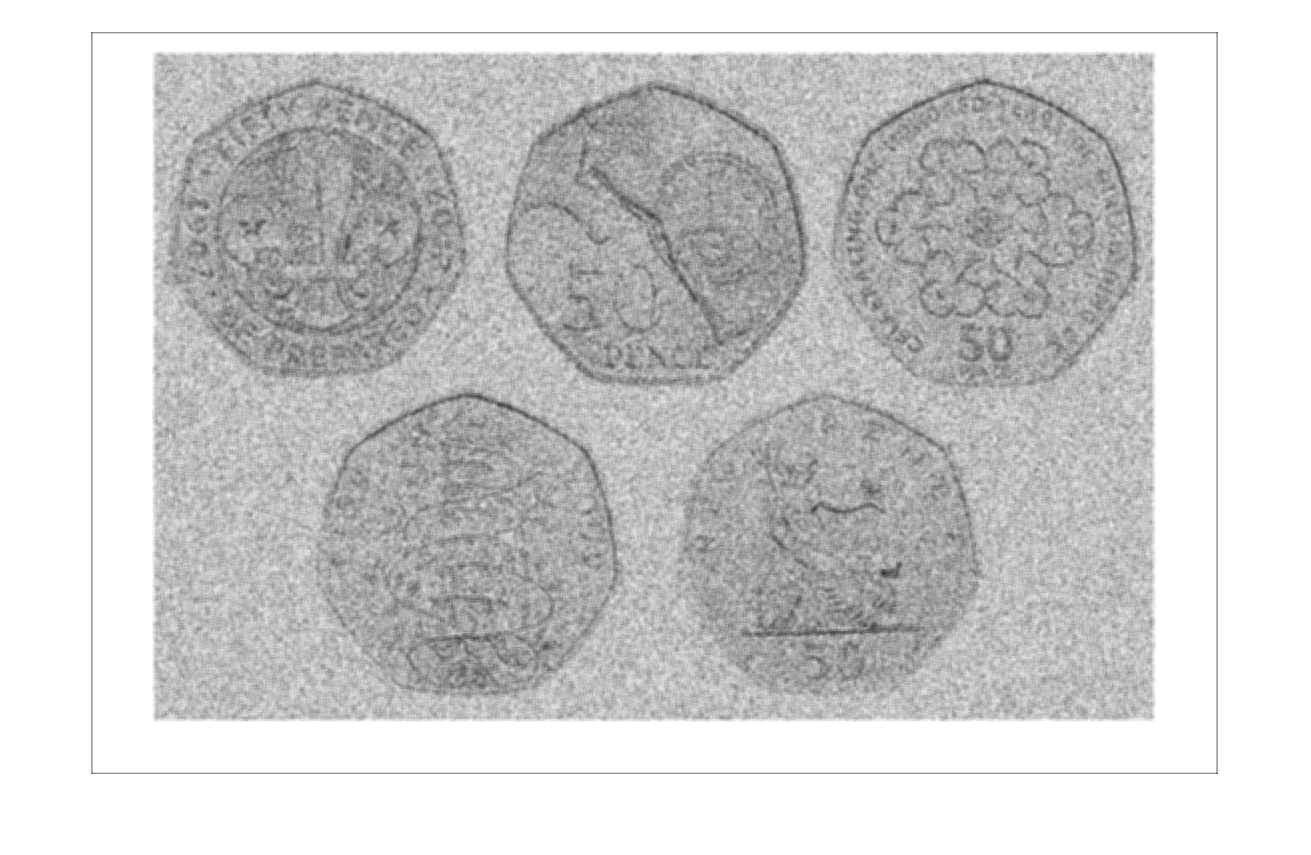

imshow(coins_filtered, cm_coins);


%h2=medfilt2(hsize2);
I=imread("im_coins_noisy.png");
coins_filtered3=medfilt2(I,hsize2);

Error using medfilt2
Expected input number 1, A, to be two-dimensional.

Error in medfilt2>parse_inputs (line 107)
validateattributes(a, ...

Error in medfilt2 (line 49)
[a, mn, padopt] = parse_inputs(args{:});

imshow(coins_filtered3,cm_coins);
